#  MDM exercise

The purpose of this exercise is the prediction of the population of two species (Snowshoe Hare and Canada Lynx), respectively, predator and prey of each other.

Exercise start with data declaration:

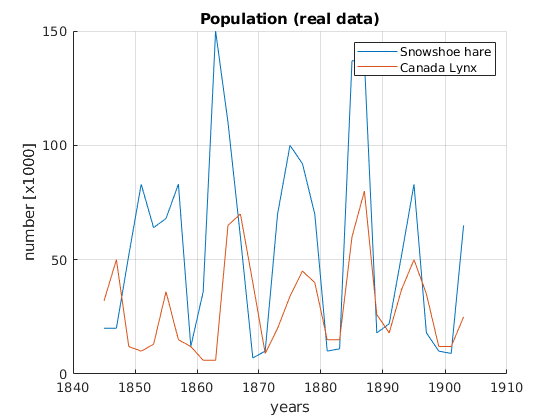

load_data
figure
hold on
plot(years, snowshoe_hare)
plot(years, canada_lynx)
grid on
xlabel("years")
ylabel("number [x1000]")
title("Population (real data)")
legend("Snowshoe hare","Canada Lynx")

First point require to use the DMD model to forecast the future popolation state.

A DMD function is declared at the end of this notebook.

X = [snowshoe_hare; canada_lynx];
[phi_dmd, lambda_dmd, b_dmd] = DMD(X(:,1:end-1), X(:,2:end),2); % as reported, two series means 2 eigenvalues

The eigenvalues found are real. This values seems to not fit the expected behaviour. I try to reconstruct the series starting from values found.

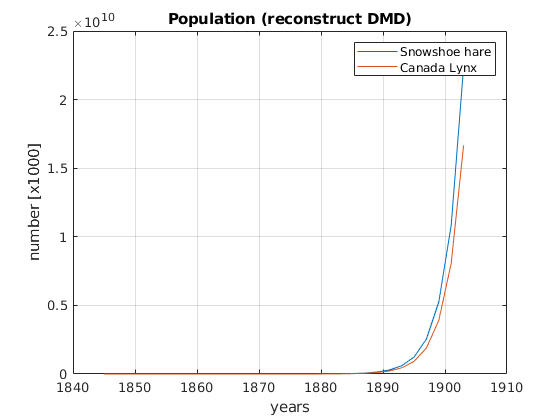

%lambda_dmd(1,1) = imag(lambda_dmd(1,1))*i;
%lambda_dmd(2,2) = imag(lambda_dmd(2,2))*i;
%lambda_dmd
X_rec_dmd = phi_dmd*diag(b_dmd)*exp(diag(lambda_dmd)*[0:length(years)-1]);
figure()
plot(years, real(X_rec_dmd));
grid on
xlabel("years")
ylabel("number [x1000]")
title("Population (reconstruct DMD)")
legend("Snowshoe hare","Canada Lynx")

Starting from a visual analysis I decided to make an hypotesis on the start values for optDMD. 

hyp_lambda_dmd = [0.2265 + 0.4722i,0;0,0.2265 - 0.4722i];
hyp_lambda_dmd = [0.0 + 0.4722i,0;0,0.0 - 0.4722i];

period_dmd = diag(1./(imag(hyp_lambda_dmd)/(2*pi*2))) % dt = 2 years -> for this reason the 2 at denominator

period_dmd =    26.6124
  -26.6124


The period of 26.6 years seems to overstimate the period found from a visual analysis of the data, but could . 

That expresses a sinusoidal behaviour that diverges during the years. Probably due to the low number of point that doesn't permit to correctly identify the modes .

As suggested from the text we start to analyze the same results using optdmd library.

rank = 2;
mode = 1;               % use full data
[w_odmd,lambda_odmd,b_odmd] = optdmd(X,[0:dt:length(years)*dt-1],rank,mode,[],diag(hyp_lambda_dmd));

step 1 err 8.803237e+04 lambda 3.333333e-01
step 2 err 8.741486e+04 lambda 1.111111e-01
step 3 err 8.699641e+04 lambda 3.703704e-02
step 4 err 8.659027e+04 lambda 1.234568e-02
step 5 err 8.611701e+04 lambda 4.115226e-03
step 6 err 8.550372e+04 lambda 1.371742e-03
step 7 err 8.472740e+04 lambda 4.572474e-04
step 8 err 8.386080e+04 lambda 1.524158e-04
step 9 err 8.305405e+04 lambda 5.080526e-05
step 10 err 8.241170e+04 lambda 1.693509e-05
step 11 err 8.194808e+04 lambda 5.645029e-06
step 12 err 8.163343e+04 lambda 1.881676e-06
step 13 err 8.143298e+04 lambda 6.272255e-07
step 14 err 8.131465e+04 lambda 2.090752e-07
step 15 err 8.125018e+04 lambda 6.969172e-08
step 16 err 8.121754e+04 lambda 2.323057e-08
step 17 err 8.120194e+04 lambda 7.743524e-09
step 18 err 8.119481e+04 lambda 2.581175e-09
step 19 err 8.119165e+04 lambda 8.603916e-10
step 20 err 8.119028e+04 lambda 2.867972e-10
step 21 err 8.118969e+04 lambda 9.559907e-11
step 22 err 8.118944e+04 lambda 3.186636e-11
step 23 err 8.11893

period_odmd = (1./(imag(lambda_odmd)/(2*pi*2)))

period_odmd =    19.9462
  -19.9462


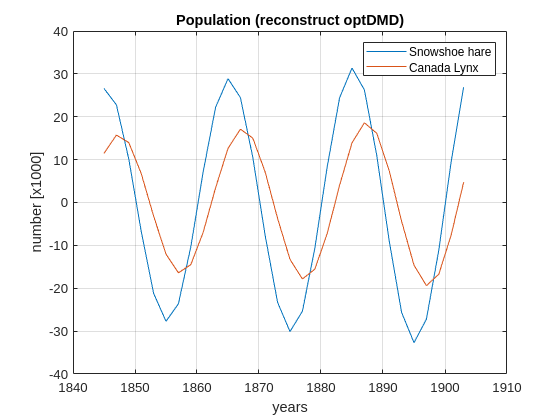

X_rec_optdmd = w_odmd*diag(b_odmd)*exp((lambda_odmd)*[0:length(years)-1]);
figure()
plot(years, real(X_rec_optdmd));
grid on
xlabel("years")
ylabel("number [x1000]")
title("Population (reconstruct optDMD)")
legend("Snowshoe hare","Canada Lynx")

Trying to improve the results I'll try bagging mode as suggested from the text. 

num_p =  100;
num_bag = 20;
lambda_vet = zeros(2,num_p); 
v = [0:dt:length(years)*dt-1];
for ii = 1:num_p
    columns = sort(randperm(length(years),num_bag)); % returns a row vector containing k unique integers selected randomly from 1 to n.
    X_red = X(:,columns); % taken data
    years_red = v(columns);
    [w_jbodmd,lambda_jbodmd,b_jbodmd] = optdmd(X_red,years_red,2,mode,varpro_opts('ifprint',0),lambda_odmd);
    lambda_vet(:,ii) = lambda_jbodmd;   
end
lambda_vet

lambda_vet =    0.0104 + 0.7142i  -0.0071 + 0.5647i   0.0165 + 0.6033i   0.0406 + 0.6953i   0.0011 + 0.6790i   0.0086 + 0.6489i  -0.0182 + 0.6620i  -0.0095 + 0.5673i   0.0415 + 0.6459i  -0.0144 + 0.5755i  -0.0035 + 0.5779i   0.0461 + 0.5991i   0.0242 + 0.6103i   0.0083 + 0.6326i  -0.0022 + 0.6140i  -0.0365 + 0.6319i  -0.0009 + 0.6507i  -0.0089 + 0.6076i   0.0100 + 0.5330i   0.0021 + 0.6122i  -0.0012 + 0.5743i   0.0106 + 0.6101i   0.0129 + 0.6950i   0.0503 + 0.7554i   0.0342 + 0.6625i   0.0001 + 0.6187i  -0.0368 + 0.5648i   0.0502 + 0.6335i   0.0061 + 0.6463i   0.0055 + 0.6939i   0.0127 + 0.6204i  -0.0011 + 0.4709i   0.0005 + 0.6610i  -0.0075 + 0.5766i  -0.0084 + 0.5996i  -0.0210 + 0.5700i   0.0069 + 0.6153i  -0.0093 + 0.5311i   0.0037 + 0.6468i   0.0229 + 0.6347i  -0.0176 + 0.6189i  -0.0159 + 0.5925i  -0.0013 + 0.5953i   0.0023 + 0.6090i   0.0016 + 0.6701i   0.0033 + 0.5541i  -0.0149 + 0.5469i  -0.0076 + 0.5976i   0.0173 + 0.5880i  -0.0170 + 0.5255i
   0.0104 - 0.7142i  -0.0071 - 0.564

histfit(1./(imag(lambda_vet(1,:))/(2*pi*2)))
title("Eigenvalues period distribution")
str_e = sprintf('mean=%0.2f variance=%0.2f',(mean(1./(imag(lambda_vet(2,:))/(2*pi*2)))),(var(1./(imag(lambda_vet(2,:))/(2*pi*2)))))

str_e = 'mean=-20.31 variance=3.09'

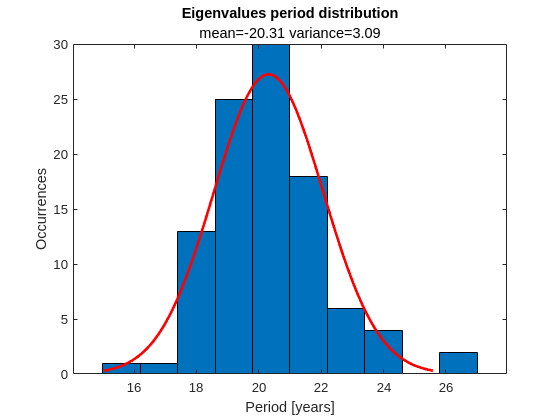

%subtitle(["mean=",num2str(mean(1./(imag(lambda_vet(2,:))/(2*pi*2)))),", variance=",num2str(var(1./(imag(lambda_vet(2,:))/(2*pi*2)))),")"])
subtitle(str_e)
ylabel("Occurrences")
xlabel("Period [years]")

histfit(real(lambda_vet(1,:)))
title('Eigenvalues real distribution')
str_e = sprintf('mean=%0.4f variance=%0.4f',(mean(imag(lambda_vet(2,:)))),(mean(real(lambda_vet(2,:)))))

str_e = 'mean=-0.6231 variance=0.0021'

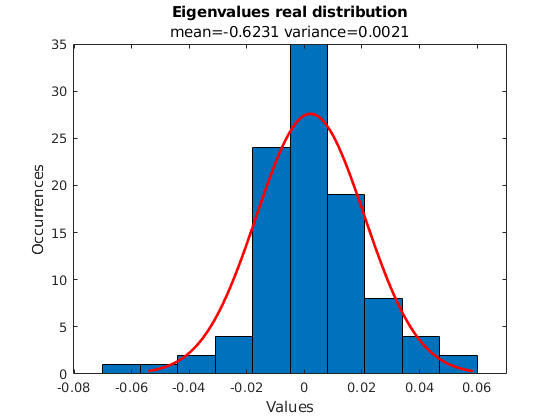

subtitle(str_e)

ylabel("Occurrences")
xlabel("Values")


mean_result(1,1) = mean(lambda_vet(1,:))

mean_result = 0.0021 + 0.6231i

mean_result(2,1) = mean(lambda_vet(2,:))

mean_result =    0.0021 + 0.6231i
   0.0021 - 0.6231i


period_bodmd = 1./(imag(mean_result)/(2*pi*2))

period_bodmd =    20.1669
  -20.1669


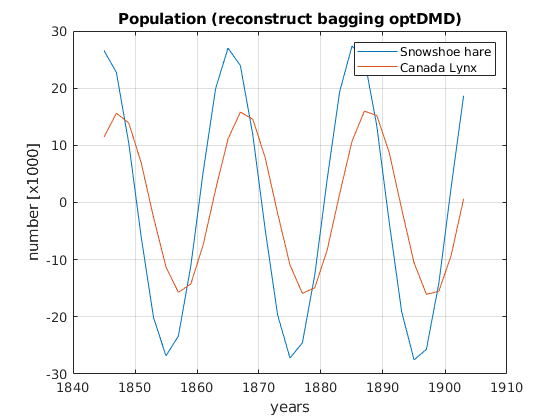



X_rec_boptdmd = w_odmd*diag(b_odmd)*exp((mean_result)*[0:length(years)-1]);
figure()
plot(years, real(X_rec_boptdmd));
grid on
xlabel("years")
ylabel("number [x1000]")
title("Population (reconstruct bagging optDMD)")
legend("Snowshoe hare","Canada Lynx")

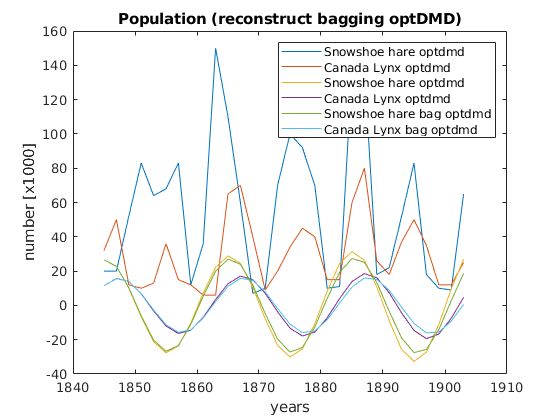


figure()
plot(years, real(X));
hold on
plot(years, real(X_rec_optdmd));
plot(years, real(X_rec_boptdmd));
xlabel("years")
ylabel("number [x1000]")
title("Population (reconstruct bagging optDMD)")
legend("Snowshoe hare optdmd","Canada Lynx optdmd","Snowshoe hare optdmd","Canada Lynx optdmd", "Snowshoe hare bag optdmd","Canada Lynx bag optdmd")

The results between optdmd and the same algorithm with bagging applied don't change the results much. Eigenvalues remain more or less the same and there is only a small change in the modes.

## Definition of exact DMD

function [Phi, Lambda, b] = DMD(X,Xprime,r)
[U,Sigma,V] = svd(X,'econ');
Ur = U(:,1:r);
Sigmar = Sigma(1:r,1:r);
Vr = V(:,1:r);
Atilde = (Ur)'*Xprime*Vr/Sigmar;
[W,Lambda] = eig(Atilde); 
Phi = Xprime*(Vr/Sigmar)*W;
alpha1 = Sigmar*Vr(1,:)';
b = (W*Lambda)\alpha1;
end